# Ejemplos de procesamiento de la imagen basada en el histograma en Matlab

## **Histograma**

El histograma de una imagen es una función discreta que representa el número de píxeles en una imagen por cada nivel de intensidad. La función que nos proporciona el histograma es *imhist,* que lo crea realizando n niveles de intensidad igualmente espaciados cada uno representando un rango de valores de intensidad o valores de color. 

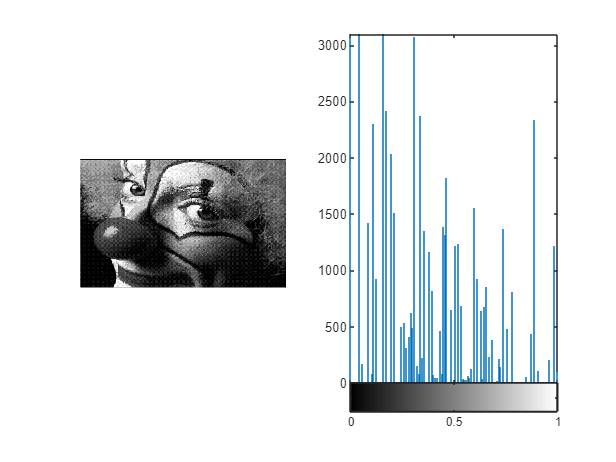

load clown % Imagen indexada de matlab guardada en variables X y map
I=ind2gray(X,map);  % I es una imagen de intensidad double entre 0 y 1
figure
subplot(1,2,1), imshow(I)
subplot(1,2,2), imhist(I,128) 

**Ejecute el código anterior y modifique el número de niveles del histograma.**

## **Ajuste de la intensidad **

La función *imadjust* mapea los valores de intensidad de una imagen a un nuevo rango según los valores de los parámetros de entrada: puede ampliar y reducir y soporta distintas funciones de transferencia. Puede realizar tres tipos de ajuste de imagen: 

- rangos explícitos de intensidades (input and output cropping), 

- corrección gamma, y

- ecualización de la imagen. 

*imadjust* no se usa únicamente con imágenes con niveles grises, también se utiliza con imágenes de color operando sobre las componentes rojo, verde y azul independientemente. 

La función *imadjust* trabaja con los valores low, high, bot y top entre 0 y 1 (double), por ello conviene que la imagen de entrada tenga también este tipo de formato, como se hace en el siguiente ejemplo: 

J=imadjust(I, [low  high], [bot   top], gamma);  % con low, high, bot y top entre 0 y 1

**Introduzca el siguiente código: **

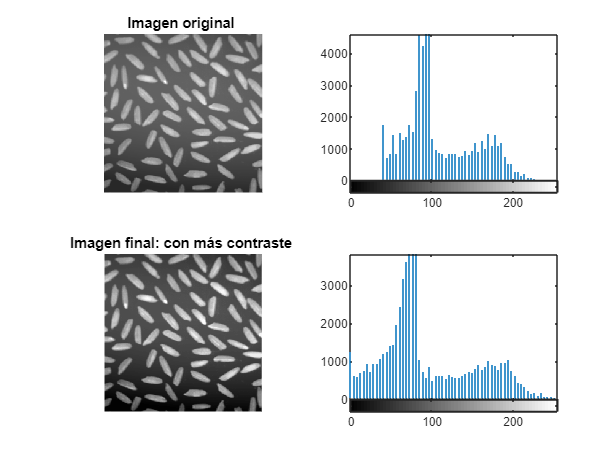

Ir=imread('.\imagenes\rice.tif'); %Imagen de intensidad de tipo uint8
I=im2double(Ir); %Imagen de intensidad de tipo double  (rango entre 0 y 1)
J=imadjust(Ir,[0.15 0.9], [0 1]);  %gamma, por defecto, vale uno: conversion lineal
figure
subplot(2,2,1), imshow(Ir); title('Imagen original ');
subplot(2,2,2), imhist(Ir,64);
subplot(2,2,3), imshow(J); title('Imagen final: con más contraste ');
subplot(2,2,4), imhist(J,64);

Como se puede observar **aumenta el contraste** (el rango [low  high] de la imagen de entrada se convierte en un rango [bot top] mayor). 

Se puede, sean cual sean los valores máximo y mínimo de la imagen de entrada (double entre 0 y 1) ajustarlo a los máximos de 0 y 1 (en la imagen de salida) haciendo: 

J=imadjust(I,[min(min(I)) max(max(I))], [0 1]); %Ajuste del contraste al maximo 

**Ejecute las líneas anteriores y modifique los márgenes de entrada y salida aumentando el contraste.**

De forma similar se puede **disminuir el contraste** haciendo:

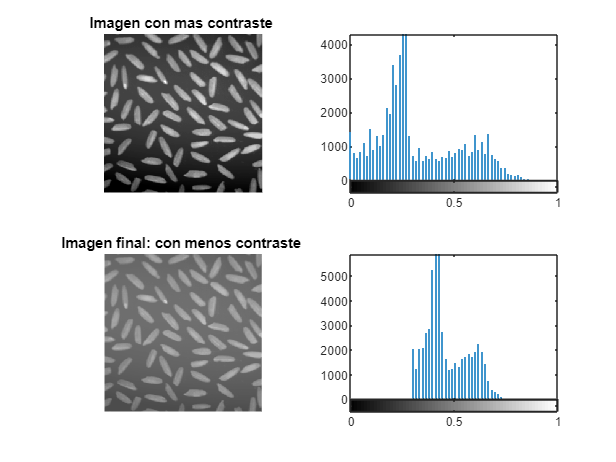

JJ=imadjust(J,[0 1], [0.3 0.8]); %Valores entre 0 y 1 se ajustan entre 0.3 y 0.8: baja contraste
figure, subplot(2,2,1), imshow(J); title('Imagen con mas contraste ');
subplot(2,2,2), imhist(J,64);
subplot(2,2,3), imshow(JJ); title('Imagen final: con menos contraste ');
subplot(2,2,4), imhist(JJ,64);

**Ejecute las líneas anteriores y modifique los márgenes de entrada y salida disminuyendo el contraste.**

También se puede variar el **brillo** de la imagen provocando desplazamientos de intensidad de los valores de los píxeles en el histograma. 

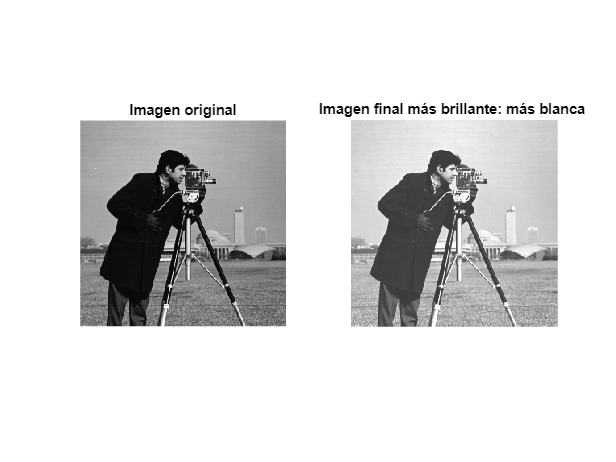

I=imread('.\imagenes\cameraman.tif');  %Imagen de intensidad de tipo uint8
I=im2double(I);  %Imagen de intensidad de tipo double (rango entre 0 y 1)
J=imadjust(I,[0 0.8], [0.2 1]);  %Aumenta brillo (suma 0.2 a niveles de gris de partida: la distancia del 
% nivel de gris máx y mín es el mismo a la entrada y a la salida porque se desplazan todos los niveles de gris la misma cantidad)
figure, subplot(1,2,1), imshow(I); title('Imagen original');
subplot(1,2,2), imshow(J); title('Imagen final más brillante: más blanca ');

**Ejecute las líneas anteriores y modifique los márgenes de entrada y salida  para modificar solamente el brillo (no el contraste).**

## **Corrección gamma**

La corrección gamma es una operación de asociación de intensidades. Se hace corresponder un valor de intensidad de la imagen a otro valor, en este caso usando una función exponencial. Si x es una intensidad de entrada, la intensidad de salida es y, tal que y=x ^ gamma. *imadjust *realiza la corrección gamma utilizando el formato: 

J= imadjust (I, [ ], [ ], gamma); 

donde I es la imagen, gamma es el valor de exponente deseado, y las matrices vacías impiden el recorte de intensidades. Se muestra un ejemplo de la corrección gamma para la imagen forest:

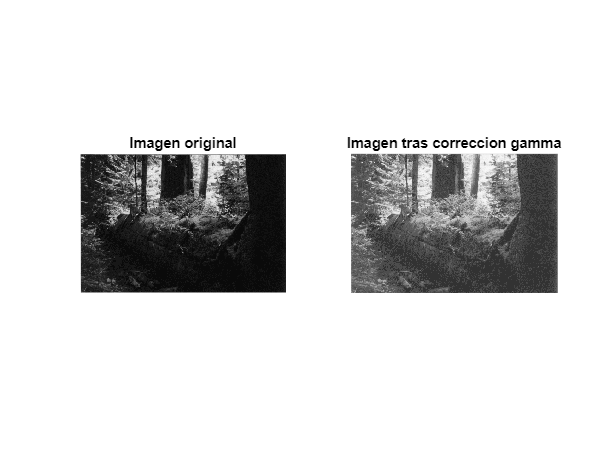

[X,map]=imread('.\imagenes\forest.tif');
I=ind2gray(X,map);
J=imadjust(I,[],[],0.5);
figure
subplot(1,2,1), imshow(I); title('Imagen original');
subplot(1,2,2), imshow(J); title('Imagen tras correccion gamma');

**Ejecute las líneas anteriores y verifique el efecto de distintos valores de gamma.**

## **Ecualización del histograma**

La ecualización del histograma redistribuye los valores de intensidad de manera que el histograma acumulativo de la imagen sea aproximadamente lineal. La función *histeq* implementa la ecualización del histograma. 

Cuantos menos niveles de intensidad de salida se utilicen, más plano es el histograma. 

Los comandos que se muestran a continuación crean dos imágenes ecualizadas. Una con 32 niveles de salida, J, y otra con 4, K. Comparando las dos figuras, se observa que el histograma asociado con la imagen ecualizada con los cuatro niveles de salida es más plano: 

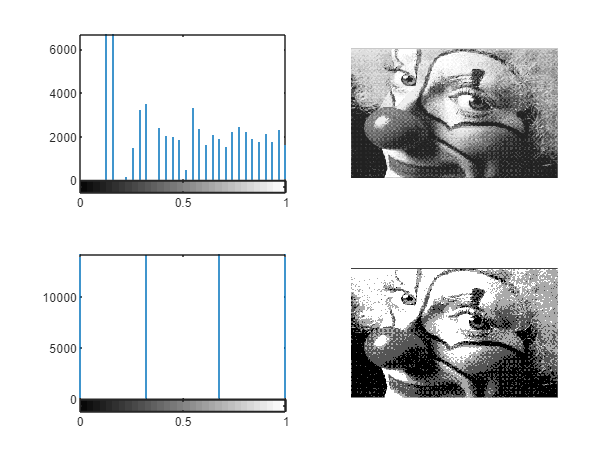

load clown          % imagen indexada de matlab definida a traves de X y map 
I=ind2gray(X,map);  % imagen de intensidad double entre 0 y 1 
J=histeq(I,32); 
K=histeq(I,4); 
figure 
subplot(2,2,1), imhist(J,32) 
subplot(2,2,2), imshow(J) 
subplot(2,2,3), imhist(K,32) 
subplot(2,2,4), imshow(K) 

También se puede obtener la gráfica de transferencia entre los valores de entrada-salida:

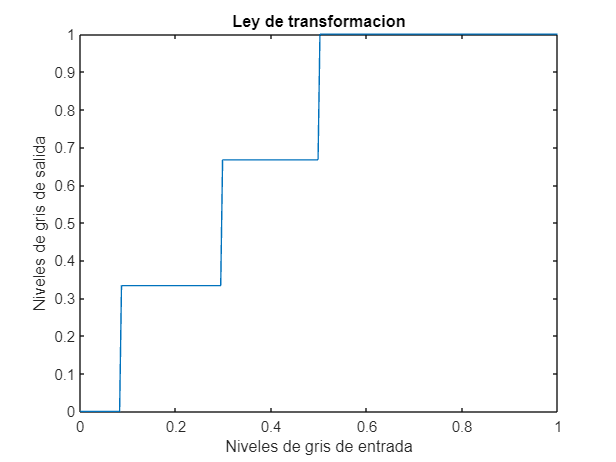

[K,T]=histeq(I,4); 
%Los 256 niveles de gris de entrada entre 0 y 1 se transforman en los niveles T
figure, plot((0:255)/255,T); title('Ley de transformacion');
xlabel('Niveles de gris de entrada'); ylabel('Niveles de gris de salida');

**Ejecute las líneas anteriores y verifique el efecto del número de valores en el histograma ecualizado y en la gráfica de transferencia.**

**Logaritmo de una imagen. **

En este ejemplo se trabajará sobre una imagen muy oscura (bazo.bmp desplazando su nivel de gris mínimo al negro) y se aumentará su contraste realizando el logaritmo de la imagen. Previamente se habrá calculado el valor de k adecuado.

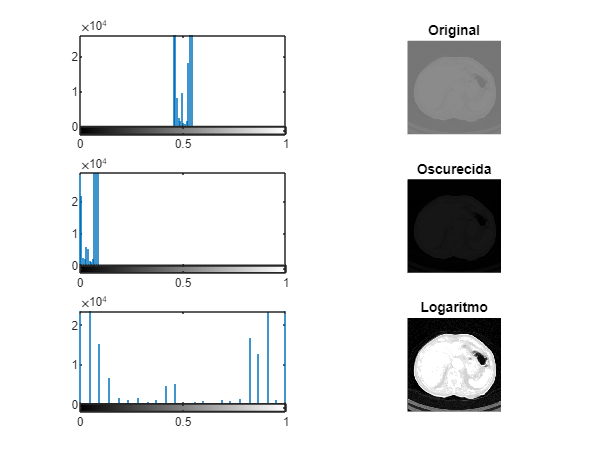

[JOrig,map]=(imread('.\imagenes\bazo.bmp'));
J=im2double(ind2gray(JOrig,map));
figure, 
subplot(3,2,1), imhist(J,128);
subplot(3,2,2), imshow(J); title('Original');
vmin=min(min(J)); vmax=max(max(J));
J1=imadjust(J, [vmin vmax], [0 vmax-vmin]);
subplot(3,2,3), imhist(J1,128);
subplot(3,2,4), imshow(J1); title('Oscurecida');
Z=max(max(J1)); k=1/log10(1+Z); X=k*log10(1+J1);
subplot(3,2,5), imhist(X,128);
subplot(3,2,6), imshow(X);title('Logaritmo');

**Ejecute las líneas anteriores y pruebe distintos valores de k.**

**Otros comandos de Matlab**

Con el comando *imfinfo *puede obtener información sobre una imagen guardada en un fichero. 

Asimismo puede testear las variables usadas (o cargadas con el comando *load*) viendo el workspace o con el comando *who *o *whos *en Matlab.